#### Test Case 1: 13 Cambridge Communities - Trapezoidal with dt = 0.05

clc; clear; close all;

t_start = 0;
t_stop = 100;
timestep = 0.05;

[P, x_start, p, u] = initializeCambridgeCommunities();

% test FE function
tic;
[X, trapNewtonLastIter] = trapezoidal(P, x_start, p, u, t_stop, timestep);   %t_start is always 0
trapElapsedTime = toc;

%% Convert SEIR cell time series to matrix
for i = 1:size(X,2)
    trapState(:,i) = convertSeirCellToMat(X(:,i));
end

save('Technical-Challenge/techChallengeStats.mat', 'trapState', '-append');
save('Technical-Challenge/techChallengeStats.mat', 'trapElapsedTime', '-append');
save('Technical-Challenge/techChallengeStats.mat', 'trapNewtonLastIter', '-append');

clc; clear; close all;

t_start = 0;
t_stop = 100;
timestep_desc = "\Deltat = 0.05 day";

load('Technical-Challenge/techChallengeStats.mat');
matState = trapState;
model_type = 'Trapezoidal';
seir_ylabel = '# Individuals';

plotSEIRTestCase(t_start, t_stop, matState, model_type, timestep_desc, seir_ylabel);

#### Test Case 2: 13 Cambridge Communities - Forward Euler

clc; clear; close all;

t_start = 0;
t_stop = 100;

%select input evaluation function
eval_u = 'GenInputVec';

%select model evaluation function
eval_f = 'EVALF';

[P, x_start, p, u] = initializeCambridgeCommunities();

for timestep = [0.05, 0.1, 0.2, 0.5, 1]

    tic;
    [X] = forwardEuler(P, eval_f, x_start, p, eval_u, t_start, t_stop, timestep);
    feElapsedTime = toc;
    
    %% Convert SEIR cell time series to matrix
    for i = 1:size(X,2)
        feState(:,i) = convertSeirCellToMat(X(:,i)); 
    end
    
    matState = feState;
%     model_type = 'Forward Euler';
%     timestep_desc = strcat("\Deltat = ", num2str(timestep), " day");
%     seir_ylabel = '# Individuals';
    
    % plotSEIRTestCase(t_start, t_stop, matState, model_type, timestep_desc, seir_ylabel);
    
    if timestep == 0.05
        save('Technical-Challenge/techChallengeStats.mat', 'feState', '-append');
        save('Technical-Challenge/techChallengeStats.mat', 'feElapsedTime', '-append');
        
    elseif timestep == 0.1
        feState_dt01 = feState;
        save('Technical-Challenge/techChallengeStats.mat', 'feState_dt01', '-append');
        save('Technical-Challenge/techChallengeStats.mat', 'feElapsedTime', '-append');
        
    elseif timestep == 0.2
        feState_dt02 = feState;
        save('Technical-Challenge/techChallengeStats.mat', 'feState_dt02', '-append');
        save('Technical-Challenge/techChallengeStats.mat', 'feElapsedTime', '-append');
        
    elseif timestep == 0.5
        feState_dt05 = feState;
        save('Technical-Challenge/techChallengeStats.mat', 'feState_dt05', '-append');
        save('Technical-Challenge/techChallengeStats.mat', 'feElapsedTime', '-append');
        
    elseif timestep == 1 
        feState_dt1 = feState;
        save('Technical-Challenge/techChallengeStats.mat', 'feState_dt1', '-append');
        save('Technical-Challenge/techChallengeStats.mat', 'feElapsedTime', '-append');        
        
    end
end    

#### Error Plot between Test Case 1 and 2  (Reference Trapezoidal VS Forward Euler)

clc; clear; close all;

load('Technical-Challenge/techChallengeStats.mat');

t_start = 0;
t_stop = 100;

refTimestep = 0.05;
refState = trapState;

expTimestep = 1;
expState = feState_dt1;

expDtType = "fixed";
expModelType = strcat(' Forward Euler with \Deltat = ', num2str(expTimestep), ' day');

[percentErrorDayStateCell, sumPercentErrorDayState, populationErrorDayStateCell, sumPopulationErrorDayState]... 
    = calculateError(expDtType, refTimestep, expTimestep, refState, expState);

% plotSEIRError(t_start, t_stop, expTimestep, expModelType,...
%     percentErrorDayStateCell, sumPercentErrorDayState, populationErrorDayStateCell, sumPopulationErrorDayState);

[maxPercentErrorS, maxPercentErrorE, maxPercentErrorI, maxPercentErrorR] = getMaxSEIR(sumPercentErrorDayState);
[maxPopulationErrorS, maxPopulationErrorE, maxPopulationErrorI, maxPopulationErrorR] = getMaxSEIR(sumPopulationErrorDayState);

#### Test Case 3: 13 Cambridge Communities - Adaptive Trapezoidal

% clc; clear; close all;

t_start = 0;
t_stop = 100;
timestep = 0.05;

[P, x_start, p, u] = initializeCambridgeCommunities();

tic;
[X, trapAdaptiveT, trapAdaptiveNewtonLastIter] = trapezoidalAdaptive(P, x_start, p, u, t_stop, timestep); %t_start is always 0

At time t = 0
At time t = 1
At time t = 2
At time t = 3
At time t = 4
At time t = 5
At time t = 6
At time t = 7
At time t = 8
At time t = 9
At time t = 10
At time t = 11
At time t = 12
At time t = 13
At time t = 14
At time t = 15
At time t = 16
At time t = 17
At time t = 18
At time t = 19
At time t = 20
At time t = 21
At time t = 22
At time t = 23
At time t = 24
At time t = 25
At time t = 26
At time t = 27
At time t = 28
At time t = 29
At time t = 30
At time t = 31
At time t = 32
At time t = 33
At time t = 34
At time t = 35
At time t = 36
At time t = 37
At time t = 38
At time t = 39
At time t = 40
At time t = 41
At time t = 42
At time t = 43
At time t = 44
At time t = 45
At time t = 46
At time t = 47
At time t = 48
At time t = 49
At time t = 50
At time t = 51
At time t = 52
At time t = 53
At time t = 54
At time t = 55
At time t = 56
At time t = 57
At time t = 58
At time t = 59
At time t = 60
At time t = 61
At time t = 62
At time t = 63
At time t = 64
At time t = 65
At time t = 66
At ti

trapAdaptiveElapsedTime = toc;

%% Convert SEIR cell time series to matrix
for i = 1:size(X,2)
    trapAdaptiveState(:,i) = convertSeirCellToMat(X(:,i));
end

save('Technical-Challenge/techChallengeStats.mat', 'trapAdaptiveState', '-append');
save('Technical-Challenge/techChallengeStats.mat', 'trapAdaptiveElapsedTime', '-append');
save('Technical-Challenge/techChallengeStats.mat', 'trapAdaptiveT', '-append');
save('Technical-Challenge/techChallengeStats.mat', 'trapAdaptiveNewtonLastIter', '-append');

clc; clear; close all;

t_start = 0;
t_stop = 100;
timestep_desc = ' Adaptive Time Steps';

load('Technical-Challenge/techChallengeStats.mat');
matState = trapAdaptiveState;
model_type = 'Trapezoidal';
seir_ylabel = '# Individuals';

plotSEIRTestCase(t_start, t_stop, matState, model_type, timestep_desc, seir_ylabel);

#### Error Plot between Test Case 1 and 3 (Reference Trapezoidal VS Adaptive Trapezoidal)

f =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [681 559 560 420]
       Units: 'pixels'

  Show all properties


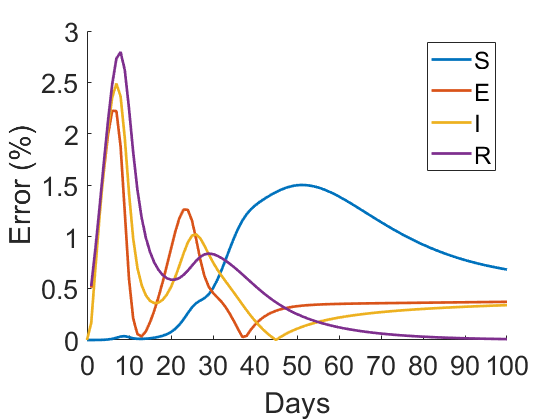

f =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [1 1 1]
    Position: [681 559 560 420]
       Units: 'pixels'

  Show all properties


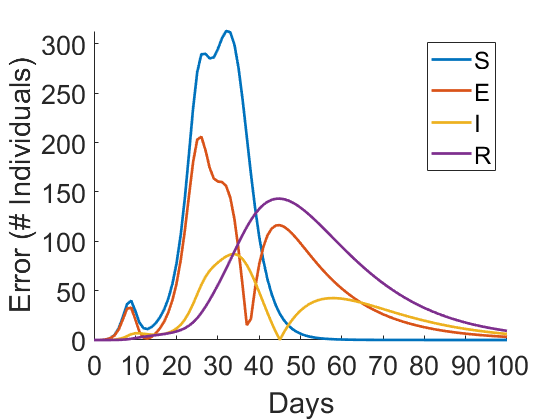

%clc; clear; close all;

load('Technical-Challenge/techChallengeStats.mat');

t_start = 0;
t_stop = 100;

expDtType = "adaptive";
refTimestep = 0.05;
expTimestep = trapAdaptiveT;
expModelType = ' Trapezoidal with Adaptive Time Steps';

refState = trapState;
expState = trapAdaptiveState;

[percentErrorDayStateCell, sumPercentErrorDayState, populationErrorDayStateCell, sumPopulationErrorDayState]... 
    = calculateError(expDtType, refTimestep, expTimestep, refState, expState);

plotSEIRError(t_start, t_stop, expTimestep, expModelType,...
    percentErrorDayStateCell, sumPercentErrorDayState, populationErrorDayStateCell, sumPopulationErrorDayState);


[maxPercentErrorS, maxPercentErrorE, maxPercentErrorI, maxPercentErrorR] = getMaxSEIR(sumPercentErrorDayState);
[maxPopulationErrorS, maxPopulationErrorE, maxPopulationErrorI, maxPopulationErrorR] = getMaxSEIR(sumPopulationErrorDayState);

#### Test Case 4: 13 Cambridge Communities - Trapezoidal with dt = 0.1

clc; clear; close all;

t_start = 0;
t_stop = 100;
timestep = 0.1;

[P, x_start, p, u] = initializeCambridgeCommunities();

tic;
[X, trapNewtonLastIter_dt01] = trapezoidal(P, x_start, p, u, t_stop, timestep);   %t_start is always 0
trapElapsedTime_dt01 = toc;

%% Convert SEIR cell time series to matrix
for i = 1:size(X,2)    
    trapState_dt01(:,i) = convertSeirCellToMat(X(:,i));    
end

save('Technical-Challenge/techChallengeStats.mat', 'trapState_dt01', '-append');
save('Technical-Challenge/techChallengeStats.mat', 'trapElapsedTime_dt01', '-append');
save('Technical-Challenge/techChallengeStats.mat', 'trapNewtonLastIter_dt01', '-append');

#### Test Case 5: 13 Cambridge Communities - Trapezoidal with dt = 0.2

clc; clear; close all;

t_start = 0;
t_stop = 100;
timestep = 0.2;

[P, x_start, p, u] = initializeCambridgeCommunities();

tic;
[X, trapNewtonLastIter_dt02] = trapezoidal(P, x_start, p, u, t_stop, timestep);   %t_start is always 0
trapElapsedTime_dt02 = toc;

%% Convert SEIR cell time series to matrix
for i = 1:size(X,2)  
    trapState_dt02(:,i) = convertSeirCellToMat(X(:,i));  
end

save('Technical-Challenge/techChallengeStats.mat', 'trapState_dt02', '-append');
save('Technical-Challenge/techChallengeStats.mat', 'trapElapsedTime_dt02', '-append');
save('Technical-Challenge/techChallengeStats.mat', 'trapNewtonLastIter_dt02', '-append');

#### Test Case 6: 13 Cambridge Communities - Trapezoidal with dt = 0.5

clc; clear; close all;

t_start = 0;
t_stop = 100;
timestep = 0.5;

[P, x_start, p, u] = initializeCambridgeCommunities();

tic;
[X, trapNewtonLastIter_dt05] = trapezoidal(P, x_start, p, u, t_stop, timestep);   %t_start is always 0
trapElapsedTime_dt05 = toc;

%% Convert SEIR cell time series to matrix
for i = 1:size(X,2)
    
    trapState_dt05(:,i) = convertSeirCellToMat(X(:,i));
    
end

save('Technical-Challenge/techChallengeStats.mat', 'trapState_dt05', '-append');
save('Technical-Challenge/techChallengeStats.mat', 'trapElapsedTime_dt05', '-append');
save('Technical-Challenge/techChallengeStats.mat', 'trapNewtonLastIter_dt05', '-append');

#### Test Case 7: 13 Cambridge Communities - Trapezoidal with dt = 1

clc; clear; close all;

t_start = 0;
t_stop = 100;
timestep = 1;

[P, x_start, p, u] = initializeCambridgeCommunities();

tic;
[X, trapNewtonLastIter_dt1] = trapezoidal(P, x_start, p, u, t_stop, timestep);   %t_start is always 0
trapElapsedTime_dt1 = toc;

%% Convert SEIR cell time series to matrix
for i = 1:size(X,2)
    
    trapState_dt1(:,i) = convertSeirCellToMat(X(:,i));
    
end

save('Technical-Challenge/techChallengeStats.mat', 'trapState_dt1', '-append');
save('Technical-Challenge/techChallengeStats.mat', 'trapElapsedTime_dt1', '-append');
save('Technical-Challenge/techChallengeStats.mat', 'trapNewtonLastIter_dt1', '-append');

#### Error Plot between Test Case 1 and 4, 5, 6, 7 with Trap fixed time step

clc; clear; close all;

load('Technical-Challenge/techChallengeStats.mat');

t_start = 0;
t_stop = 100;

expDtType = "fixed";
refTimestep = 0.05;
expTimestep = 0.5;
expModelType = strcat(' Trapezoidal with \Deltat = ', num2str(expTimestep), ' day');

refState = trapState;
expState = trapState_dt05;

[percentErrorDayStateCell, sumPercentErrorDayState, populationErrorDayStateCell, sumPopulationErrorDayState]... 
    = calculateError(expDtType, refTimestep, expTimestep, refState, expState);

% plotSEIRError(t_start, t_stop, expTimestep, expModelType,...
%     percentErrorDayStateCell, sumPercentErrorDayState, populationErrorDayStateCell, sumPopulationErrorDayState);

[maxPercentErrorS, maxPercentErrorE, maxPercentErrorI, maxPercentErrorR] = getMaxSEIR(sumPercentErrorDayState);
[maxPopulationErrorS, maxPopulationErrorE, maxPopulationErrorI, maxPopulationErrorR] = getMaxSEIR(sumPopulationErrorDayState);

#### Rerun Simulations Several Times to Measure Elapsed Times

clc; clear; close all;

numSimulation = 5;

t_start = 0;
t_stop = 100;

timestep = 0.05;
[P, x_start, p, u] = initializeCambridgeCommunities(); 

for i = 1:numSimulation
    tic;
    [X, trapAdaptiveT, trapAdaptiveNewtonLastIter] = trapezoidalAdaptive(P, x_start, p, u, t_stop, timestep); %t_start is always 0
    trapAdaptiveElapsedTime(i) = toc;
end
trapAdaptiveElapsedTime = sort(trapAdaptiveElapsedTime);
save('Technical-Challenge/techChallengeStats.mat', 'trapAdaptiveElapsedTime', '-append');

clc; clear; close all;

numSimulation = 5;

t_start = 0;
t_stop = 100;

timestep = 1;
[P, x_start, p, u] = initializeCambridgeCommunities();
for i = 1:numSimulation
    tic;
    [X, trapNewtonLastIter_dt1] = trapezoidal(P, x_start, p, u, t_stop, timestep);   %t_start is always 0
    trapElapsedTime_dt1(i) = toc;
end
trapElapsedTime_dt1 = sort(trapElapsedTime_dt1);
save('Technical-Challenge/techChallengeStats.mat', 'trapElapsedTime_dt1', '-append');

timestep = 0.5;
[P, x_start, p, u] = initializeCambridgeCommunities();  
for i = 1:numSimulation
    tic;
    [X, trapNewtonLastIter_dt05] = trapezoidal(P, x_start, p, u, t_stop, timestep);   %t_start is always 0
    trapElapsedTime_dt05(i) = toc;
end
trapElapsedTime_dt05 = sort(trapElapsedTime_dt05);
save('Technical-Challenge/techChallengeStats.mat', 'trapElapsedTime_dt05', '-append');

timestep = 0.2;
[P, x_start, p, u] = initializeCambridgeCommunities();
for i = 1:numSimulation
    tic;
    [X, trapNewtonLastIter_dt02] = trapezoidal(P, x_start, p, u, t_stop, timestep);   %t_start is always 0
    trapElapsedTime_dt02(i) = toc;
end
trapElapsedTime_dt02 = sort(trapElapsedTime_dt02);
save('Technical-Challenge/techChallengeStats.mat', 'trapElapsedTime_dt02', '-append');

timestep = 0.1;
[P, x_start, p, u] = initializeCambridgeCommunities();
for i = 1:numSimulation
    tic;
    [X, trapNewtonLastIter_dt01] = trapezoidal(P, x_start, p, u, t_stop, timestep);   %t_start is always 0
    trapElapsedTime_dt01(i) = toc;
end
trapElapsedTime_dt01 = sort(trapElapsedTime_dt01);
save('Technical-Challenge/techChallengeStats.mat', 'trapElapsedTime_dt01', '-append');

timestep = 0.05;
[P, x_start, p, u] = initializeCambridgeCommunities();
for i = 1:numSimulation
    tic;
    [X, trapNewtonLastIter] = trapezoidal(P, x_start, p, u, t_stop, timestep);   %t_start is always 0
    trapElapsedTime(i) = toc;
end
trapElapsedTime = sort(trapElapsedTime);
save('Technical-Challenge/techChallengeStats.mat', 'trapElapsedTime', '-append');

clc; clear; close all;

numSimulation = 5;

t_start = 0;
t_stop = 100;
timestep = 1;

eval_u = 'GenInputVec';
eval_f = 'EVALF';

timestep = 1;
[P, x_start, p, u] = initializeCambridgeCommunities();
for i = 1:numSimulation
    tic;
    [X] = forwardEuler(P, eval_f, x_start, p, eval_u, t_start, t_stop, timestep);
    feElapsedTime_dt1(i) = toc;
end
feElapsedTime_dt1 = sort(feElapsedTime_dt1);
save('Technical-Challenge/techChallengeStats.mat', 'feElapsedTime_dt1', '-append');

timestep = 0.5;
[P, x_start, p, u] = initializeCambridgeCommunities();
for i = 1:numSimulation
    tic;
    [X] = forwardEuler(P, eval_f, x_start, p, eval_u, t_start, t_stop, timestep);
    feElapsedTime_dt05(i) = toc;
end
feElapsedTime_dt05 = sort(feElapsedTime_dt05);
save('Technical-Challenge/techChallengeStats.mat', 'feElapsedTime_dt05', '-append');


timestep = 0.2;
[P, x_start, p, u] = initializeCambridgeCommunities();
for i = 1:numSimulation
    tic;
    [X] = forwardEuler(P, eval_f, x_start, p, eval_u, t_start, t_stop, timestep);
    feElapsedTime_dt02(i) = toc;
end
feElapsedTime_dt02 = sort(feElapsedTime_dt02);
save('Technical-Challenge/techChallengeStats.mat', 'feElapsedTime_dt02', '-append');

timestep = 0.1;
[P, x_start, p, u] = initializeCambridgeCommunities();
for i = 1:numSimulation
    tic;
    [X] = forwardEuler(P, eval_f, x_start, p, eval_u, t_start, t_stop, timestep);
    feElapsedTime_dt01(i) = toc;
end
feElapsedTime_dt01 = sort(feElapsedTime_dt01);
save('Technical-Challenge/techChallengeStats.mat', 'feElapsedTime_dt01', '-append');

timestep = 0.05;
[P, x_start, p, u] = initializeCambridgeCommunities();
for i = 1:numSimulation
    tic;
    [X] = forwardEuler(P, eval_f, x_start, p, eval_u, t_start, t_stop, timestep);
    feElapsedTime(i) = toc;
end
feElapsedTime = sort(feElapsedTime);
save('Technical-Challenge/techChallengeStats.mat', 'feElapsedTime', '-append');